## Load input

[input, Fs] = audioread("guitar_sample.mp3");
Fnyq = Fs / 2;
input = sum(input, 2) / 2; % Stero to mono
input_duration = 8;
% Fragmento de input_duration segundos
input = input(1:floor(input_duration*Fs));

## Input FFT

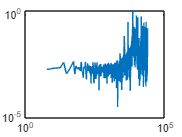

y = fft(input);
input_duration_millis = input_duration*1000;
P2 = abs(y/input_duration_millis);
P1 = P2(1:input_duration_millis/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(input_duration_millis/2))/input_duration_millis;
loglog(f,abs(P1));

## Low pass test

wp = 2000;
[b,a] = cheby2(4, 60, wp/Fnyq);
sos = tf2sos(b,a);
y= sosfilt(sos, input);
audiowrite('output.wav', y, Fs);

## Create peak filter

Q = 10;
np_filter = dsp.NotchPeakFilter('Specification',...
    'Quality factor and center frequency',...
    'QualityFactor',Q,...
    'SampleRate',Fs);
% [~,~,Bpeak,Apeak]=tf(np_filter);

## Create peak frequency vector

% Simulation time management
samples_per_frame = 10000;
total_samples = length(input);
total_frames = floor(total_samples / samples_per_frame);

% Notch filter parameters - how they vary over time

wah_period = 1;
wah_pulse = 2*pi*1/wah_period;
t_inc = 1/Fs * samples_per_frame;
%t_points = 0:t_inc:total_frames*t_inc;
t_points = logspace(1, total_frames*t_inc, samples_per_frame);
peak_frecs = cos(wah_pulse*t_points);
peak_frecs = map(peak_frecs, [-1, 1], [500, 2000]);   % Peak frequencies

% % Scope creation
scope = spectrumAnalyzer('SampleRate', Fs, ...
    'AveragingMethod','exponential',...
    'ForgettingFactor',.75,...
    'ChannelNames',{'Filter 1'},...
    'ShowLegend',true);

## Generate output

y = [];
zf = [];
% Actual simulation loop
for loop_i = 0:(total_frames-1)
    % Update filter parameters
    np_filter.CenterFrequency = peak_frecs(loop_i+1);
    upper_limit = min([loop_i*samples_per_frame + samples_per_frame, total_samples]);
    % Filter noise
    sample = input(loop_i*samples_per_frame + 1:upper_limit);

    [~, y_peak] = np_filter(sample);
   
    wp = peak_frecs(loop_i+1);
    [b,a] = cheby2(4, 30, wp/Fnyq);
    [y_lp, zf] = filter(b,a, sample, zf);
    y_frame = y_lp*0.5+ y_peak*5;
    y = [y; y_frame];
    % scope(y_lp,y_peak,y_frame);
   % pause(samples_per_frame/Fs);
end

audiowrite('output.wav', y, Fs);

function [y] = map(x, r1, r2)
relative_offset = (x - r1(1)) / (r1(2) - r1(1));
y = (relative_offset * (r2(2) - r2(1))) + r2(1);
end